## Combined Exp

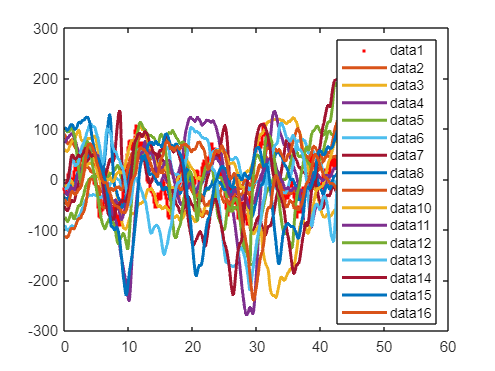

experiments = {
    % 'samsun low light window 7cm\7cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_04_22_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_08_20_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial03_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_10_11_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_11_50_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_13_41_2022_TRACK.xlsx',
    
    'Data\samsun low light window 21cm\21cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_46_43_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_48_50_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial03_DL_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_50_57_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_54_12_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_56_25_2022_TRACK.xlsx',
    
    'Data\samsun low light window 14cm\14cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_13_54_05_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_13_56_51_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial03_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_00_01_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_02_22_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_04_12_2022_TRACK.xlsx',
   
    'Data\samsun low light nowindow 21cm\21cm\trial01_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_03_18_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial02_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_05_25_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial03_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_07_26_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial04_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_09_31_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial05_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_11_33_2022_TRACK.xlsx',
    };

% readtable("samsun low light nowindow 21cm\21cm\trial02_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_05_25_2022_TRACK.xlsx")

fishes = [];

for experimentIdx = 1:length(experiments)
    experiment = experiments{experimentIdx};
    table = readtable(experiment);
    fish = table.Fish;
    fish = fish(76:end);
    fishes = [fishes detrend(fish)];
end

table_0 = readtable(experiments{1});
cage = table_0.Cage;
cage = cage(76:end);
cage = detrend(cage);

Fs = 25;              % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(cage);     % Length of signal
t = (0:L-1)*T;        % Time vector
f = Fs/L*(0:L-1);

figure,
hold on; box on;
plot(t, cage, '.r', 'LineWidth', 4);

for fish = fishes
    Fs = 25;
    t = 0:1/Fs:(length(fish)-1)/Fs;

    plot(t, fish, 'LineWidth', 2);
end

legend()

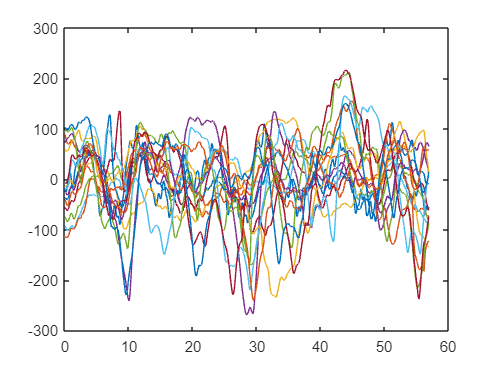

y = fishes;
u = cage;
num_outputs = length(y(1,:));

% Create an iddata object with your data
data = iddata(y, u, t(2) - t(1), 'ExperimentName', experiments);

figure, hold on, box on,
plot(t, u, t, y);

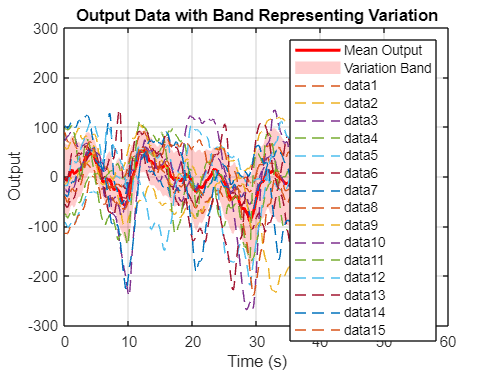

% Calculate the mean and standard deviation at each time point
y_mean = mean(y, 2);
y_std = std(y, 0, 2);

% Define the upper and lower bounds for the band
y_upper = y_mean + y_std;
y_lower = y_mean - y_std;

% Plot the mean output
figure;
plot(t, y_mean, 'r', 'LineWidth', 2);
hold on;

% Plot the band
fill([t'; flipud(t')], [y_upper; flipud(y_lower)], 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% Add labels and title
xlabel('Time (s)');
ylabel('Output');
title('Output Data with Band Representing Variation');
legend('Mean Output', 'Variation Band');
grid on;

% Optional: Plot individual output data
for i = 1:num_outputs
    plot(t, y(:, i), '--');
end

% Number of models to fit
num_models = 3;

% Initialize cell array for storing models
G_ests = cell(num_models, num_outputs);

% Define the transfer function structure for the model
K_initial = 1; % Initial guess for K
a_initial = 1; % Initial guess for a
tau_initial = 0.5; % Initial guess for tau
A_initial = 1;
w0_initial = 1;
etha_initial = 0.5;

% Loop through each output to estimate the model
for i = 1:num_outputs
    % Create idtf model with initial parameter values
    G0 = idtf(K_initial, [1 a_initial]);
    G1 = idtf(K_initial, [1 a_initial], 'InputDelay', tau_initial);
    G2 = idtf(A_initial*w0_initial^2, [1 2*etha_initial*w0_initial w0_initial^2], 'InputDelay', tau_initial);

    % Estimate the model parameters for each output
    G_ests{1, i} = pem(iddata(y(:, i), u, t(2) - t(1)), G0);
    G_ests{2, i} = pem(iddata(y(:, i), u, t(2) - t(1)), G1);
    G_ests{3, i} = pem(iddata(y(:, i), u, t(2) - t(1)), G2);
end

% Display the estimated 
% models
for i = 1:num_outputs
    for j = 1:num_models
        G_ests{j, i}
    end
end

ans =
  From input "u1" to output "y1":
   0.8199
  --------
  s + 1.57
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                 
Estimated using PEM on time domain data.
Fit to estimation data: 19.39%          
FPE: 1098, MSE: 1093                    
 
Model Properties

ans =
  From input "u1" to output "y1":
                  1.758
  exp(-0.5*s) * ---------
                s + 4.065
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients

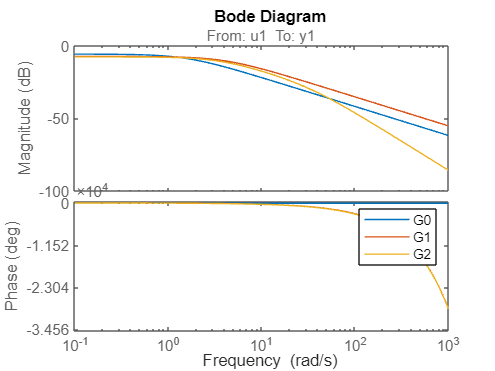

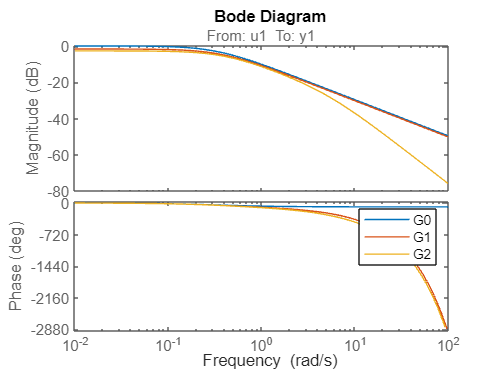

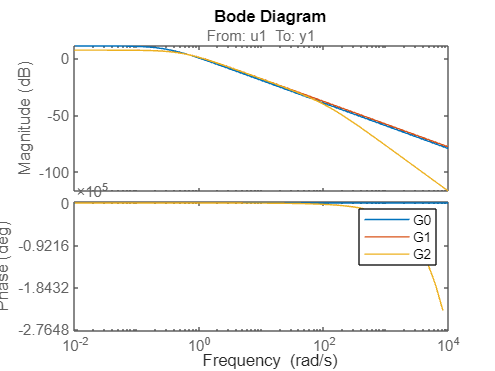

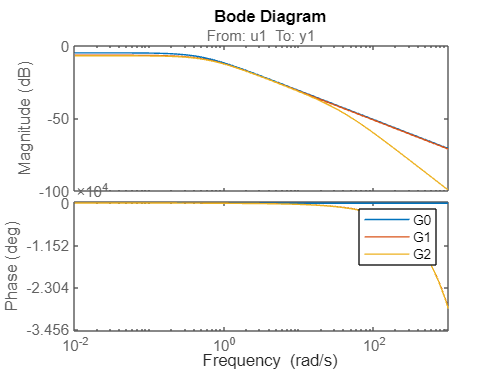

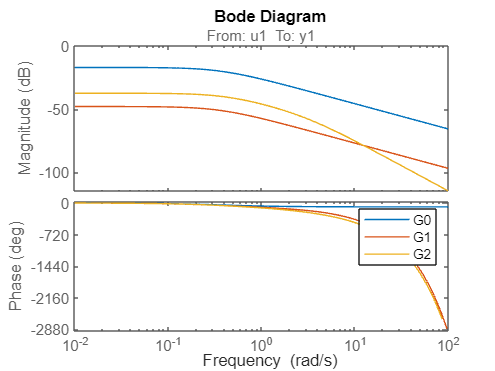

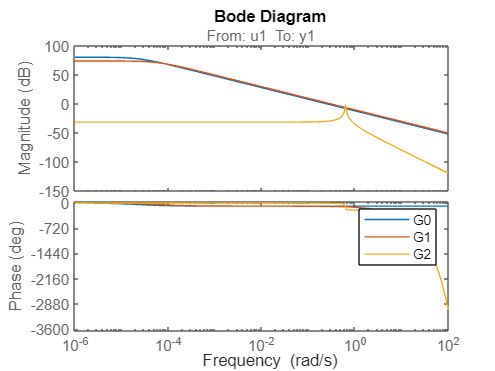

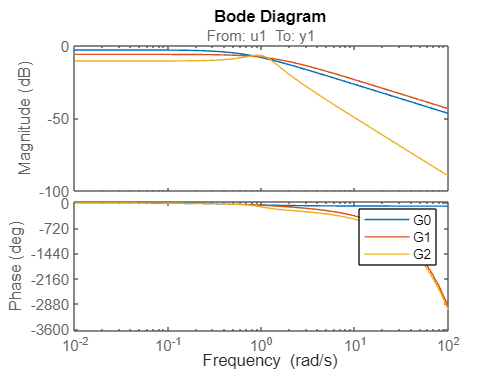

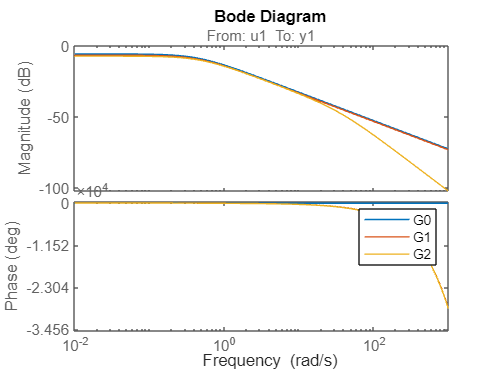

for i = 1:num_outputs
    figure, hold on, box on,
    for j = 1:num_models
        h = bodeplot(G_ests{j, i});
        % showConfidence(h,3)
    end
    legend('G0', 'G1', 'G2');
end

% Initialize cell array for storing sim outputs
% y_sims = zeros(size(y));
y_sims = cell(num_models, num_outputs);

% Simulate the model output
for i = 1:num_outputs
    for j = 1:num_models
        y_sims{j, i} = lsim(G_ests{j, i}, u, t);
    end
end

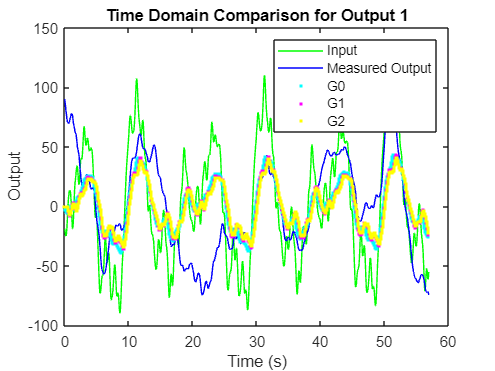

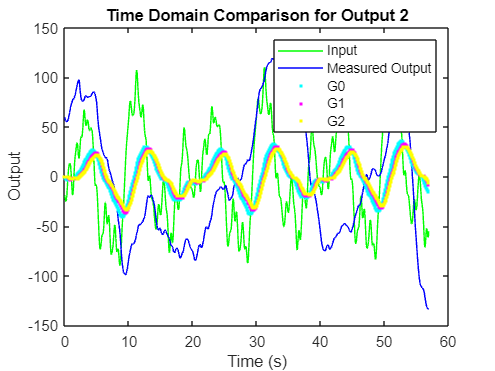

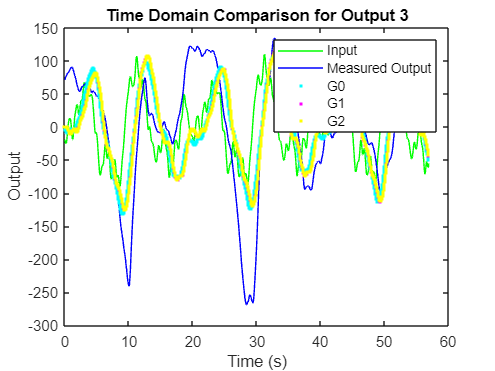

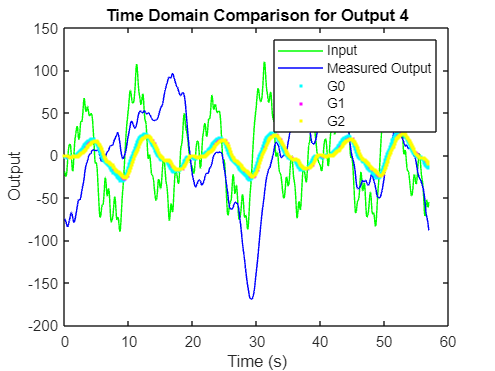

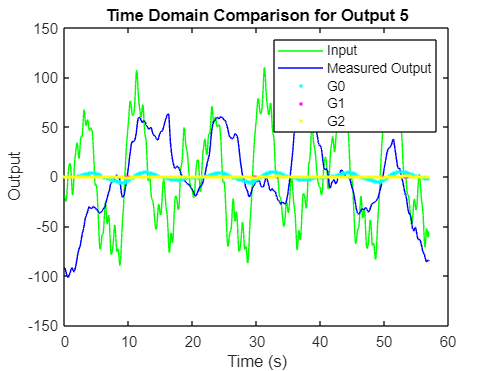

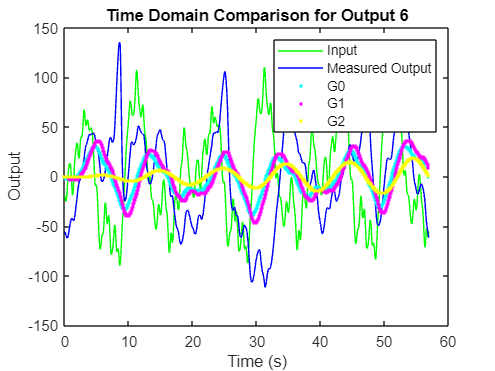

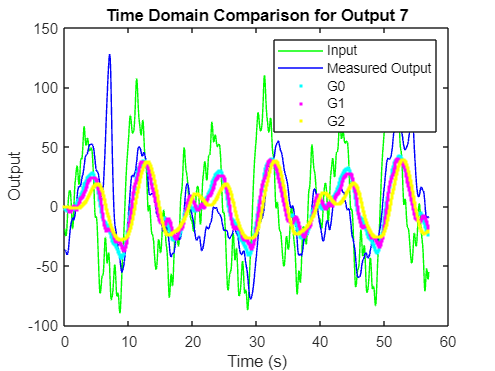

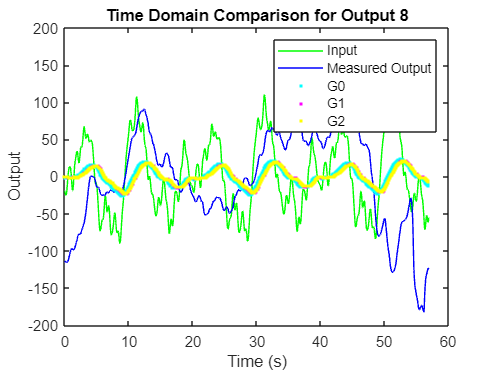

% Plot the measured output vs. simulated output in the time domain
for i = 1:num_outputs
    figure; hold on, box on,

    % subplot(num_outputs, 1, i);
    plot(t, u, 'g', t, y(:, i), 'b');
    plot(t, y_sims{1, i}, 'c.');
    plot(t, y_sims{2, i}, 'm.');
    plot(t, y_sims{3, i}, 'y.');

    legend('Input', 'Measured Output', 'G0', 'G1', 'G2');
    xlabel('Time (s)');
    ylabel('Output');
    title(['Time Domain Comparison for Output ' num2str(i)]);
end

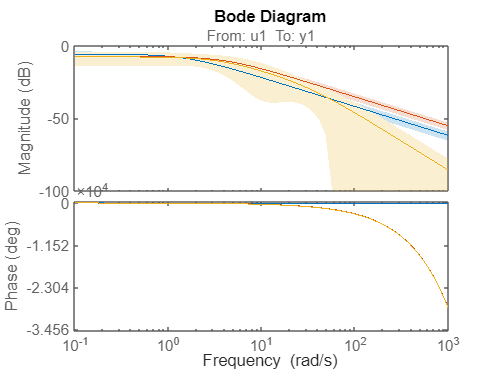

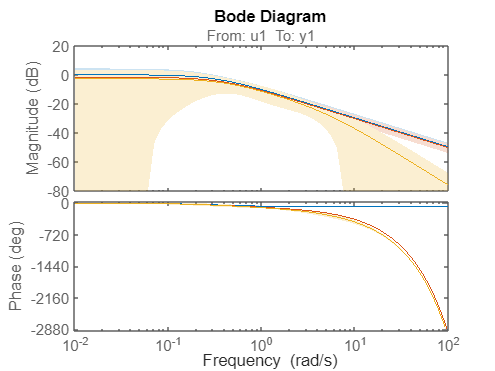

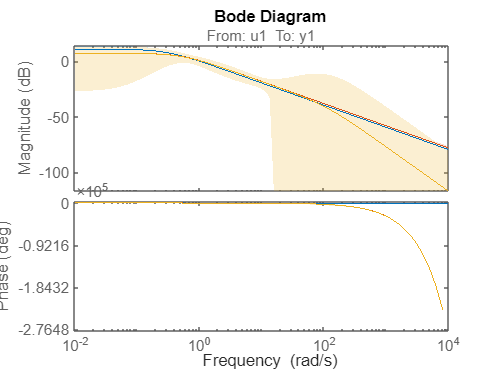

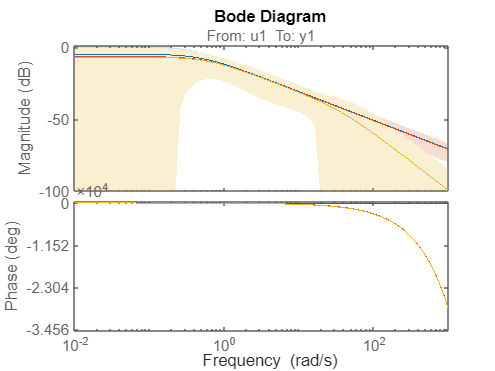

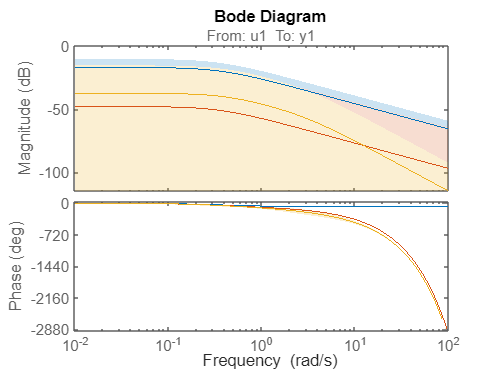

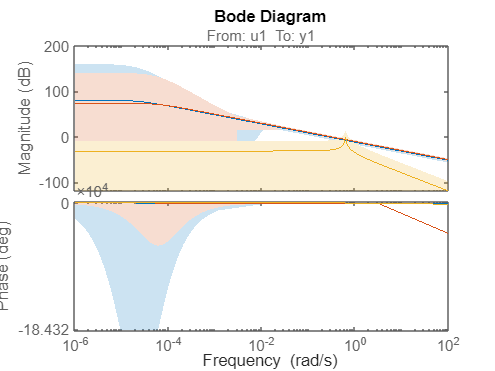

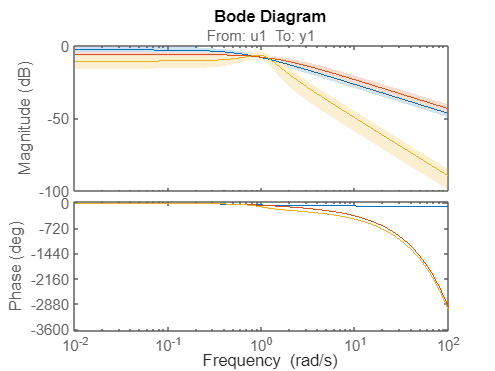

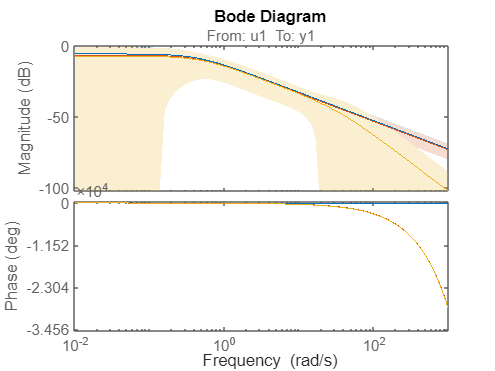

for i = 1:num_outputs
    figure, hold on,
    for j = 1:num_models
        h = bodeplot(G_ests{j, i});
        showConfidence(h,1)
    end
end

### Standard Deviation

% Convert cell array to matrix for statistical analysis
y_est = zeros(length(t), num_models, num_outputs);

for i = 1:num_models
    for j = 1:num_outputs
        y_est(:, i, j) = y_sims{i, j};
    end
end

size(y_est)

ans =         1425           3          15


% Calculate the mean and standard deviation at each time point
y_mean = mean(y, 2);
y_std = std(y, 0, 2);

% Define the upper and lower bounds for the band
y_upper = y_mean + y_std;
y_lower = y_mean - y_std;

% Preallocate arrays for storing means and standard deviations
y_est_mean = zeros(length(t), num_models);
y_est_std = zeros(length(t), num_models);
y_est_upper = zeros(length(t), num_models);
y_est_lower = zeros(length(t), num_models);

% Compute the mean and standard deviation at each time point for each model's outputs
for i = 1:num_models
    y_est_mean(:, i) = mean(y_est(:, i, :), 3);
    y_est_std(:, i) = std(y_est(:, i, :), 0, 3);
    y_est_upper(:, i) = y_est_mean(:, i) + y_est_std(:, i);
    y_est_lower(:, i) = y_est_mean(:, i) - y_est_std(:, i);
end

#### Output Data with Band Representing Variation

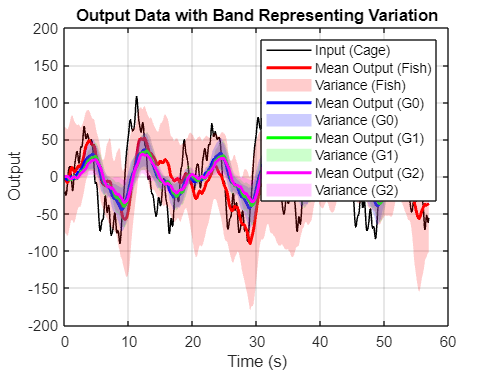

figure; 

% Plot the input
plot(t, u, 'k', 'LineWidth', 1);
hold on;

% Plot the mean output
plot(t, y_mean, 'r', 'LineWidth', 2);

% Plot the band
fill([t'; flipud(t')], [y_upper; flipud(y_lower)], 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% Add labels and title
xlabel('Time (s)');
ylabel('Output');
title('Output Data with Band Representing Variation');
grid on;

% Plot the mean estimated outputs and their bands
colors = ['b', 'g', 'm']; % Different colors for different models
for i = 1:num_models
    plot(t, y_est_mean(:, i), colors(i), 'LineWidth', 2);
    fill([t'; flipud(t')], [y_est_upper(:, i); flipud(y_est_lower(:, i))], colors(i), 'FaceAlpha', 0.2, 'EdgeColor', 'none');
end

legend('Input (Cage)', 'Mean Output (Fish)', 'Variance (Fish)', 'Mean Output (G0)', 'Variance (G0)', 'Mean Output (G1)', 'Variance (G1)', 'Mean Output (G2)', 'Variance (G2)');

G0 Only

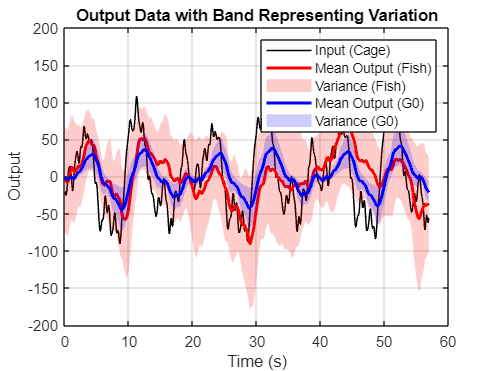

figure; 

% Plot the input
plot(t, u, 'k', 'LineWidth', 1);
hold on;

% Plot the mean output
plot(t, y_mean, 'r', 'LineWidth', 2);

% Plot the band
fill([t'; flipud(t')], [y_upper; flipud(y_lower)], 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% Add labels and title
xlabel('Time (s)');
ylabel('Output');
title('Output Data with Band Representing Variation');
grid on;

% Plot the mean estimated outputs and their bands
colors = ['b', 'g', 'm']; % Different colors for different models
i = 1;
plot(t, y_est_mean(:, i), colors(i), 'LineWidth', 2);
fill([t'; flipud(t')], [y_est_upper(:, i); flipud(y_est_lower(:, i))], colors(i), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

legend('Input (Cage)', 'Mean Output (Fish)', 'Variance (Fish)', 'Mean Output (G0)', 'Variance (G0)');

G1 only

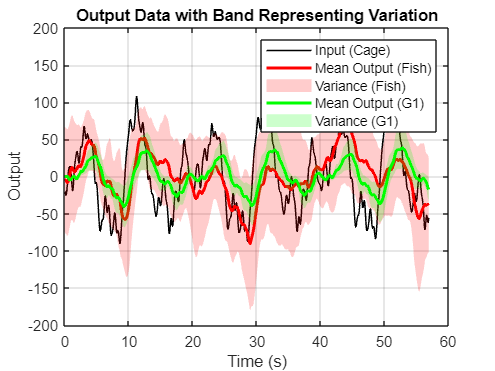

figure; 

% Plot the input
plot(t, u, 'k', 'LineWidth', 1);
hold on;

% Plot the mean output
plot(t, y_mean, 'r', 'LineWidth', 2);

% Plot the band
fill([t'; flipud(t')], [y_upper; flipud(y_lower)], 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% Add labels and title
xlabel('Time (s)');
ylabel('Output');
title('Output Data with Band Representing Variation');
grid on;

% Plot the mean estimated outputs and their bands
colors = ['b', 'g', 'm']; % Different colors for different models
i = 2;
plot(t, y_est_mean(:, i), colors(i), 'LineWidth', 2);
fill([t'; flipud(t')], [y_est_upper(:, i); flipud(y_est_lower(:, i))], colors(i), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

legend('Input (Cage)', 'Mean Output (Fish)', 'Variance (Fish)', 'Mean Output (G1)', 'Variance (G1)');

G2 only

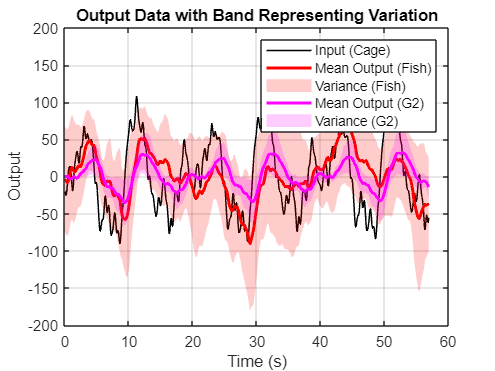

figure; 

% Plot the input
plot(t, u, 'k', 'LineWidth', 1);
hold on;

% Plot the mean output
plot(t, y_mean, 'r', 'LineWidth', 2);

% Plot the band
fill([t'; flipud(t')], [y_upper; flipud(y_lower)], 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% Add labels and title
xlabel('Time (s)');
ylabel('Output');
title('Output Data with Band Representing Variation');
grid on;

% Plot the mean estimated outputs and their bands
colors = ['b', 'g', 'm']; % Different colors for different models
i = 3;
plot(t, y_est_mean(:, i), colors(i), 'LineWidth', 2);
fill([t'; flipud(t')], [y_est_upper(:, i); flipud(y_est_lower(:, i))], colors(i), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

legend('Input (Cage)', 'Mean Output (Fish)', 'Variance (Fish)', 'Mean Output (G2)', 'Variance (G2)');

### Error ANOVA

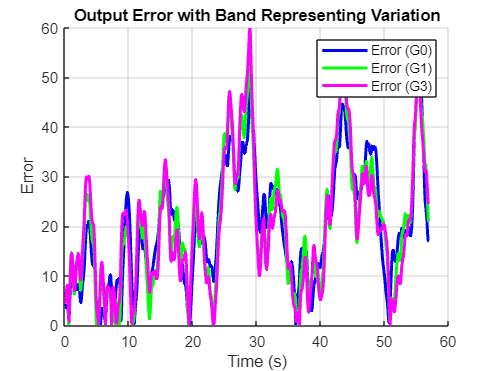

figure; hold on;

% Add labels and title
xlabel('Time (s)');
ylabel('Error');
title('Output Error with Band Representing Variation');
grid on;

% Plot the mean estimated outputs and their bands
colors = ['b', 'g', 'm']; % Different colors for different models
for i = 1:num_models
    plot(t, abs(y_mean - y_est_mean(:, i)), colors(i), 'LineWidth', 2);
    % fill([t'; flipud(t')], [y_est_upper(:, i); flipud(y_est_lower(:, i))], colors(i), 'FaceAlpha', 0.2, 'EdgeColor', 'none');
end

legend('Error (G0)', 'Error (G1)', 'Error (G3)');

#### Cumulative errors:

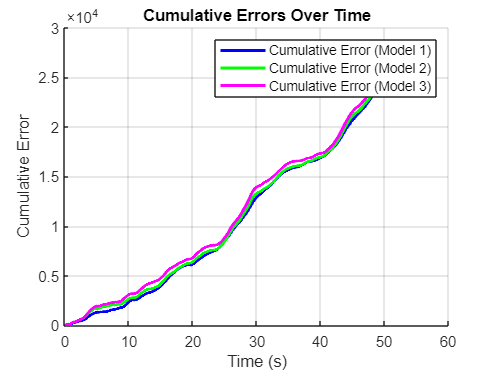

figure; hold on;

% Add labels and title
xlabel('Time (s)');
ylabel('Cumulative Error');
title('Cumulative Errors Over Time');
grid on;

% Plot the cumulative errors for the mean estimated outputs
colors = ['b', 'g', 'm']; % Different colors for different models
for i = 1:num_models
    % Calculate the absolute error
    abs_error = abs(y_mean - y_est_mean(:, i));
    
    % Calculate the cumulative sum of the absolute error
    cumulative_error = cumsum(abs_error);
    
    % Plot the cumulative error
    plot(t, cumulative_error, colors(i), 'LineWidth', 2);
end

% Add legend
legend('Cumulative Error (Model 1)', 'Cumulative Error (Model 2)', 'Cumulative Error (Model 3)');

#### Histogram of errors:

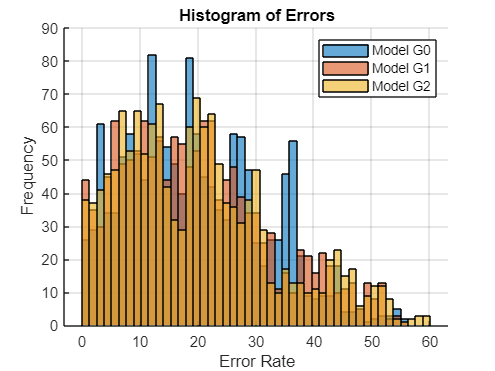

% Plot histograms of errors
figure; hold on;

% Add labels and title
xlabel('Error Rate');
ylabel('Frequency');
title('Histogram of Errors');
grid on;

% Fixed bin width
bin_width = 1 / Fs * 32; % Specify your desired bin width

% Plot histograms for each model
for i = 1:num_models
    % Calculate the absolute error
    abs_error = abs(y_mean - y_est_mean(:, i));
    histogram(abs_error, 'BinWidth', bin_width, 'DisplayName', ['Model G', num2str(i-1)]);
end

% Add legend
legend show;